m = 0.312; M = 0.400; Mw = 0.05; I = 0.00024;
l = 0.02;g = 9.81; r = 0.0335; d = 0.165;
Iw = 0.00002805*3; Ip = 0.00001972; R = 10; k_T = 0.11;
t1 = ((m+2*Mw+M)*m*l*g)/(((m+2*Mw+M)*I + (M+m+2*Mw)*m*l*l));

t2 = -(m*m*g*l*l)/((M+2*Mw)*I + (M+2*Mw)*m*l*l);

t3 = -(m*l)/((M+2*Mw+m)*I + (M+2*Mw)*m*l*l);

t4 = (I + m*l*l)/(((M+2*Mw+m)*I + ((M+2*Mw)*m*l*l))*r) ;
t5 = (2*d)/(r*(2*Iw+Ip));

% A = [0 1 0 0 0; t1 0 0 0 0; t2 0 0 0 0; 0 0 0 0 1; 0 0 0 0 0];
% B = (k_T/R)*[0 0; t3 0; t4 0; 0 0;0 t5]*[1 1; 1 -1];
A = [0 1 0 0 0 0; t1 0 0 0 0 0;0 0 0 1 0 0; t2 0 0 0 0 0; 0 0 0 0 0 1; 0 0 0 0 0 0];
B = (k_T/R)*[0 0; t3 0;0 0; t4 0; 0 0;0 t5]*[1 1; 1 -1];
n = 6;% no of states
m = 2; % no of controls
C = eye(n);
D = zeros([n,m]);
Ts = 0.001;
% ds = ss(A,B,C,D,Ts);
Plant = ss(A,B,C,D);
Planttf = tf(Plant);
Plant = c2d(Plant,Ts)


Plant =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           1       0.001           0           0           0           0
   x2      0.1678           1           0           0           0           0
   x3  -1.047e-06   -3.49e-10           1       0.001           0           0
   x4   -0.002094  -1.047e-06           0           1           0           0
   x5           0           0           0           0           1       0.001
   x6           0           0           0           0           0           1
 
  B = 
               u1          u2
   x1  -1.334e-07  -1.334e-07
   x2  -0.0002668  -0.0002668
   x3   2.328e-07   2.328e-07
   x4   0.0004656   0.0004656
   x5   0.0002882  -0.0002882
   x6      0.5763     -0.5763
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   

A = Plant.A;
B = Plant.B;

## MPC formulation

R = 0.1*eye(2);
RD = eye(2);  %Weight the slew rate - respect actuation bandwidths
Q = diag([1000,1,1,10,1,1]);
% diag([100,1,1,10,1,1])
% Q = 1;  %Single output
N = 10;  %This is the horizon for MPC

Qbar = [];
Rbar = [];
RbarD = [];
Sx = [];
Su = [];
CAB = [];
for ii = 1:N
    Qbar = blkdiag(Qbar,Q); % nNxnN matrix example if N=10, n= 5 and m = 2 we will get 50 x 50 matrix
    Rbar = blkdiag(Rbar,R); % mNxmN matrix example if N=10, n= 5 and m = 2 we will get 20 x 20 matrix
    RbarD = blkdiag(RbarD,RD); % mNxmN matrix example if N=10, n= 5 and m = 2 we will get 20 x 20 matrix
    Sx = [Sx;C*A^ii];           % nNxn matrix example if N=10, n= 5 and m = 2 we will get 50 x 5 matrix
    if ii==1
        prev_CAB = C*A^(ii-1)*B;
    else
        prev_CAB = prev_CAB + C*A^(ii-1)*B;
    end
    CAB = [prev_CAB CAB];
    Su = [Su;[CAB  zeros(n,m*N -ii*m)]];
end
Su1=  Su(:,1:2);
LL = tril(repmat(eye(2),N));
H = 2*(LL'*Rbar*LL+RbarD+Su'*Qbar*Su);
Lt_Rbart = LL'*Rbar';
b_diag = [];
for ii=0:N-1
    b_diag = [b_diag Lt_Rbart((m*ii+1):(m*ii+m),(m*ii+1):(m*ii+m))];
end
        
Fu = 2*(b_diag+Su1'*Qbar*Su)';  %Note the trick on Rbar - u(-1) is really a scalar
Fr = -2*(Qbar*Su)';
Fx = 2*(Sx'*Qbar*Su)';

Now I have to think a bit more about these constraints for the tracking case.  I'm not constraining the slew rate, so my constraint really comes down to $|u(0)+\Delta u(k)|<1$.  The $W$ matrix will be updated at each step.

G = [tril(repmat(eye(2),N));-tril(repmat(eye(2),N))];
W0 = ones(2*m*N,1)*12;
S = zeros(2*m*N,n);

The pre-computation is done.  Now let's look at an online solution using Matlab's **quadprog** command to solve the optimization problem.

Setup the initial condition and run the approach for T steps (in this case, T seconds).  For sanity's sake, I'll also turn off the reporting that quadprog typically does.

X = [1;0;0;10;3;0]; % [alpha]
T = 50;
% r = square([1:T+N+1]/6);
% r = [0;0;2;1;0;0;0;2;1;0;0;0;2;1;0];
r = zeros(1,n*N);
% Z = zeros(2,1);
Z = zeros(m*N,1);
U = [0;0];
options = optimoptions('quadprog');
options.Display = 'none';
X_alpha = [];
X_alphadot = [];
X_vel = [];
X_theta = [];
X_thetadot = [];
U1 = [];
U2 = [];
for ii = 1:T-1
    X_alpha= [X_alpha;X(1)]; %For graphing
    X_alphadot = [X_alphadot;X(2)];
    X_vel = [X_vel;X(4)];
    X_theta = [X_theta;X(5)];
    X_thetadot = [X_thetadot;X(6)];
    f = Fx*X+Fu*U+Fr*r'; %(ii:ii+N-1)';  %Sometimes people hold r(ii) here
    W = W0+[repmat(eye(2),N,1)*-U;repmat(eye(2),N,1)*U];

Solve the QP.

    [Z,~,exitflag,~]= quadprog(H,f,G,W+S*X,[],[],[],[],[],options);  %Here is the magic!
    U = U + Z(1:m);  %Just use the first item   
    U1 = [U1;U(1)];
    U2 = [U2;U(2)];

Now I'll apply the optimal control to the system.

    X = A*X+B*U;
    exitflag
end

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

% Xact =[Xact;X];

Now let's see how well that worked.

a = T-1

a = 49

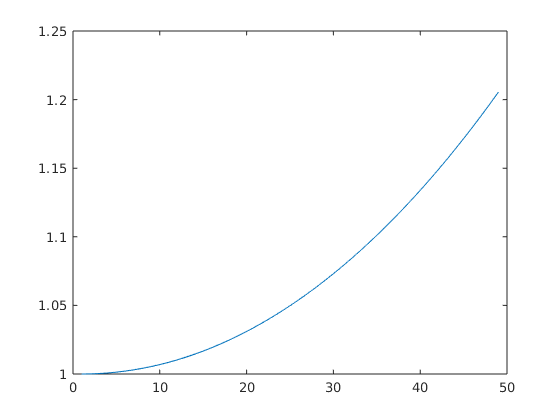

plot(X_alpha(1:a))

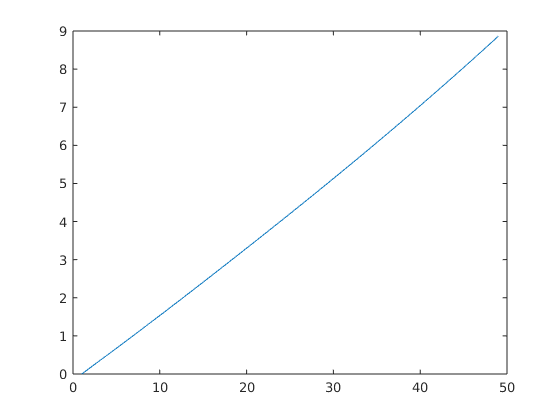

plot(X_alphadot(1:a))

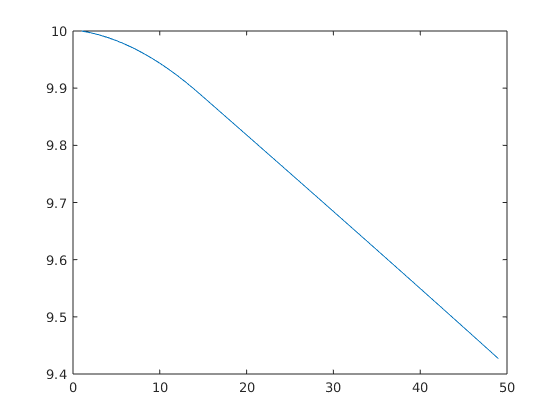

plot(X_vel(1:a))

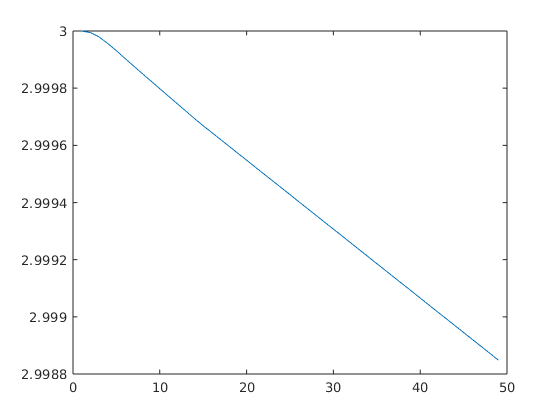

plot(X_theta(1:a))

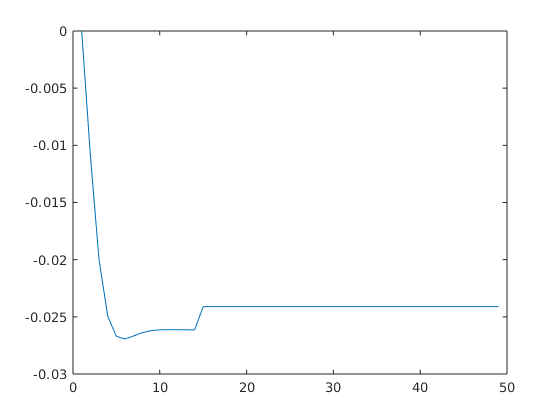

plot(X_thetadot(1:a))

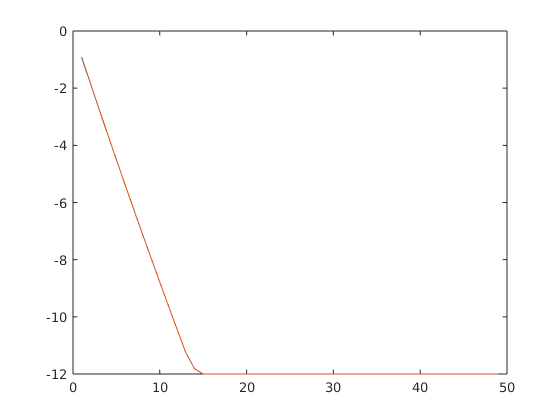

plot(U1(1:a))
hold on
plot(U2(1:a))
hold off